img = rgb2gray(imread("peppers.png"));
window = img(100:100+15, 100:100+15);
[x,y] = compareWindow(img, 98, 98, window)

x = 2

y = 2

video = VideoReader("xylophone.mp4");
frame1 = rgb2gray(video.readFrame());
rgb2gray(video.readFrame());
rgb2gray(video.readFrame());
rgb2gray(video.readFrame());
frame2 = rgb2gray(video.readFrame());

dim = size(frame1);
motions = zeros(4,4);
c = 1;


[X,Y] = meshgrid(1:16:dim(1)-15, 1:16:dim(2)-15);
U = X;
V = Y;

py = 1;
for i = 1:16:dim(1)-15
    px = 1;
    for j = 1:16:dim(2)-15
        window = frame1(i:i+15, j:j+15);
        [x,y] = compareWindow(frame2, i, j, window);
        motions(c,:) = [px,py,x,y];
        U(px,py) = x;
        V(px,py) = y;
        px = px+1;
        c = c+1;
    end
    py = py+1;
end

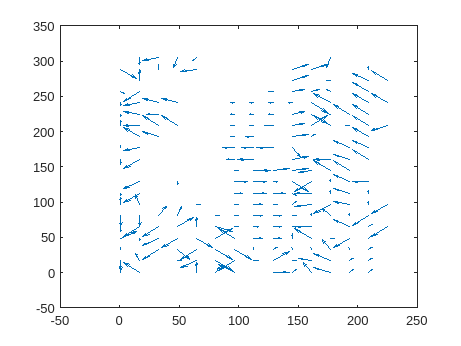

quiver(X,Y,U,V);

result = zeros(size(frame1));
for i = 1:16:dim(1)-15
    for j = 1:16:dim(2)-15
        window = frame1(i:i+15, j:j+15);
        [x,y] = compareWindow(frame2, i, j, window);
        result(i+x:i+x+15, j+y:j+y+15) = window;
    end
end

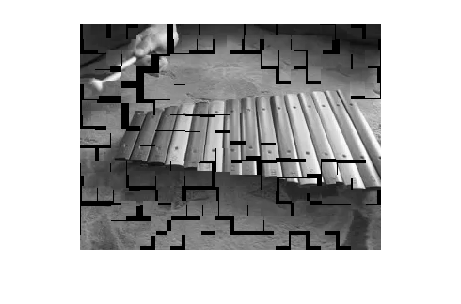

imshow(result, [])

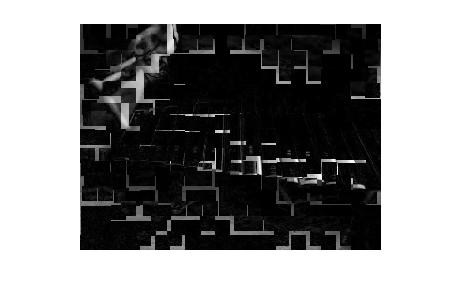

diff = abs(result-double(frame2));
imshow(diff, [])